clear;
load processed_thruster_data.mat;
dataEst = data_sine;
dataVal = data_square;
% no good results for any number of poles
np = 1:10

np =      1     2     3     4     5     6     7     8     9    10


Gss = ssest(dataEst, 1, 'InitialState', 'zero')

Gss =
  Continuous-time identified state-space model:
      dx/dt = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
           x1
   x1  -74.37
 
  B = 
            u1
   x1  0.04075
 
  C = 
             x1
   Force  57.32
 
  D = 
          u1
   Force   0
 
  K = 
       Force
   x1   17.5
 
Parameterization:
   FREE form (all coefficients in A, B, C free).
   Feedthrough: none
   Disturbance component: estimate
   Number of free coefficients: 4
   Use "idssdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using SSEST on time domain data "dataEst".
Fit to estimation data: 98.82% (prediction focus)   
FPE: 0.001275, MSE: 0.001275                        


Gest = tf(Gss)

Gest =
 
  From input "u1" to output "Force":
    2.336
  ---------
  s + 74.37
 
Continuous-time transfer function.



opt = compareOptions('InitialCondition','z')

Option set for the compare command:

             Samples: [1x0 double]
    InitialCondition: 'z'
         InputOffset: []
        OutputOffset: []
        OutputWeight: []

Description of options


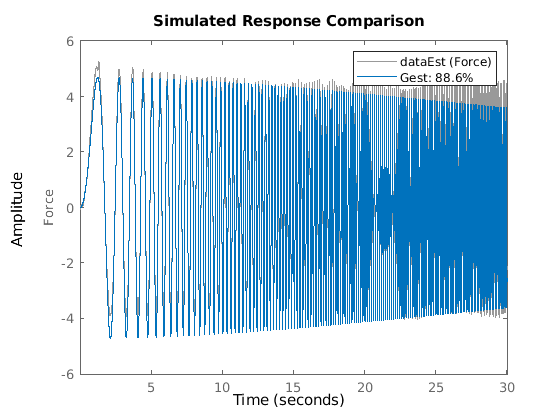

compare(dataEst, Gest, opt)

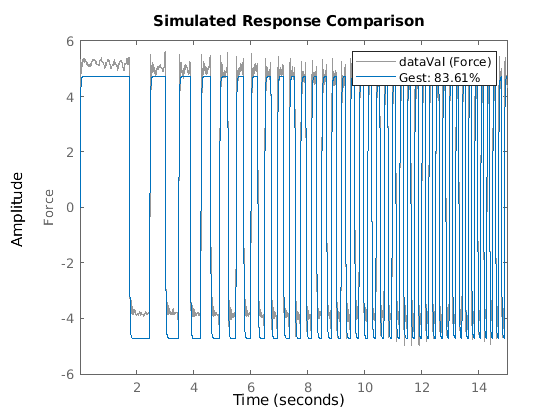

compare(dataVal, Gest, opt)